data = readtable('music1.csv');


data.Gender = categorical(data.Gender);
data.FavoriteMusicGenre = categorical(data.Genre);
data.ListeningTime = categorical(data.ListeningTime);
data.MusicWhileStudying = categorical(data.Studying);
data.PreferenceBasedOnMood = categorical(data.Mood);
data.HoursListeningperDay = categorical(data.Hours);
data.MoodImprovement = categorical(data.MoodImprovement);

summary(data)

Variables:

    Age: 1000×1 double

        Properties:
            Description:  Age
        Values:

            Min          13   
            Median       37   
            Max          60   

    Gender: 1000×1 categorical

        Properties:
            Description:  Gender
        Values:

            Female                 246   
            Male                   253   
            Non-binary             265   
            Prefer not to say      236   

    Genre: 1000×1 cell array of character vectors

        Properties:
            Description:  Genre
    Hours: 1000×1 double

        Properties:
            Description:  Hours
        Values:

            Min         0.5   
            Median      4.2   
            Max           8   

    ListeningTime: 1000×1 categorical

        Properties:
            Description:  Listening Time
        Values:

            Afternoon      208   
    

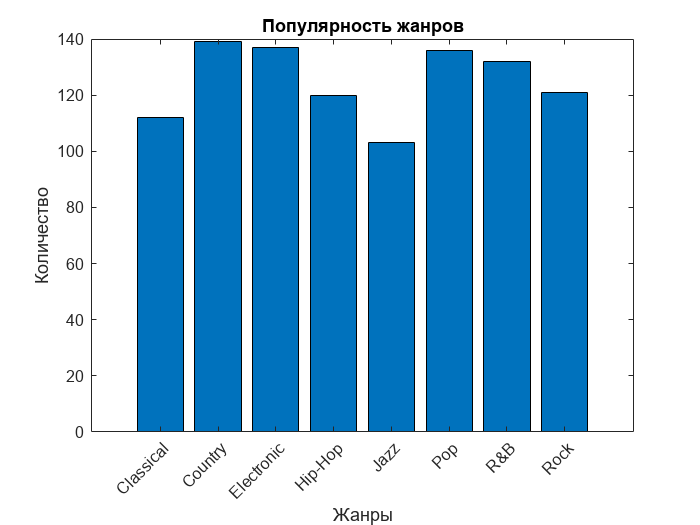


genre_counts = groupcounts(data.FavoriteMusicGenre);
genres = categories(categorical(data.FavoriteMusicGenre)); 
bar(genre_counts)
set(gca, 'XTick', 1:length(genres))  
set(gca, 'XTickLabel', genres)       
xtickangle(45)
xlabel('Жанры'), ylabel('Количество'), title('Популярность жанров')

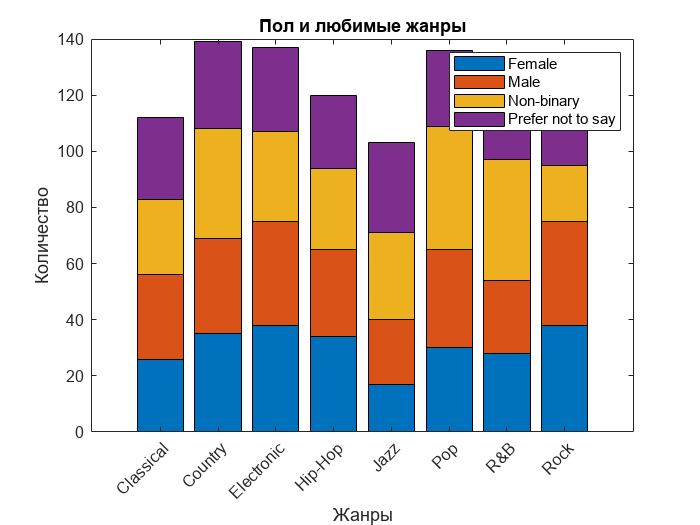

data.Gender = categorical(data.Gender);
data.FavoriteMusicGenre = categorical(data.FavoriteMusicGenre);

[table1, genres, genders] = crosstab(data.Gender, data.FavoriteMusicGenre);

genderNames = categories(data.Gender);
genreNames = categories(data.FavoriteMusicGenre);

bar(table1', 'stacked')
set(gca, 'XTick', 1:length(genreNames))
set(gca, 'XTickLabel', genreNames)
legend(genderNames)  
xlabel('Жанры'), ylabel('Количество')
title('Пол и любимые жанры')
xtickangle(45)


[p2, tbl2, stats2] = anova1(data.Hours, data.Age, 'off');
disp(['p-value (дисперсионный анализ по возрасту): ', num2str(p2)])

p-value (дисперсионный анализ по возрасту): 0.66633



[counts, genres, study] = crosstab(data.Genre, data.Studying);

% Тест хи-квадрат
[h, p, stats] = chi2test(counts);
fprintf('Хи-квадрат тест для жанров и учебы: p = %.4f\n', p);

Хи-квадрат тест для жанров и учебы: p = 0.3313


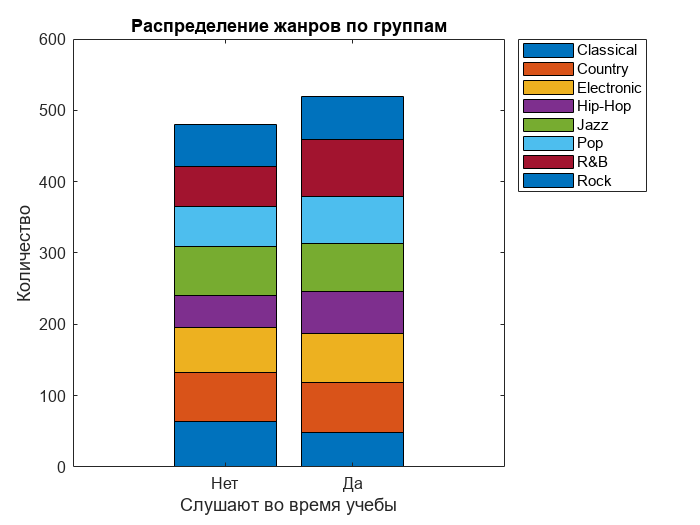

genderNames = categories(data.Gender);
genreNames = categories(data.FavoriteMusicGenre);
figure;
bar(counts', 'stacked');
set(gca, 'XTickLabel', {'Нет', 'Да'});
legend(genreNames, 'Location', 'bestoutside');
xlabel('Слушают во время учебы');
ylabel('Количество');
title('Распределение жанров по группам');

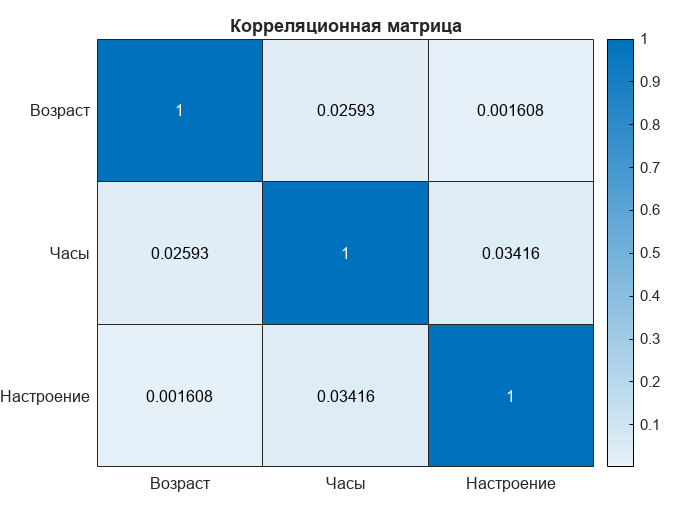


age = double(data.Age);
hours = double(data.Hours);
moodImprovement = double(data.MoodImprovement);

numerics = [age, hours, moodImprovement];

% Строим корреляционную матрицу
corrMatrix = corr(numerics, 'Rows','complete');

% Визуализируем
figure;
heatmap({'Возраст', 'Часы', 'Настроение'}, ...
        {'Возраст', 'Часы', 'Настроение'}, ...
        corrMatrix, 'ColorbarVisible','on');
title('Корреляционная матрица');

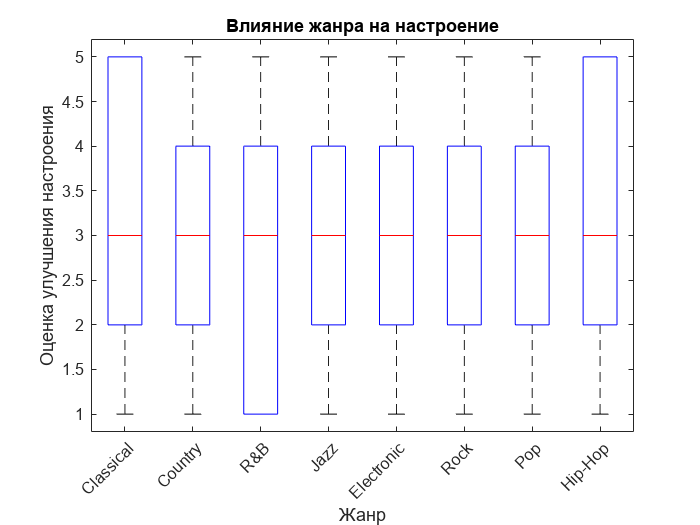



% Как жанр влияет на настроение (от 1 до 5)
figure;
boxplot(moodImprovement, data.Genre);
xlabel('Жанр');
ylabel('Оценка улучшения настроения');
title('Влияние жанра на настроение');
xtickangle(45);

function [h, p, stats] = chi2test(observed)
    expected = sum(observed,2)*sum(observed,1)/sum(observed(:));
    chi2stat = sum((observed(:)-expected(:)).^2 ./ expected(:));
    df = (size(observed,1)-1)*(size(observed,2)-1);
    p = 1 - chi2cdf(chi2stat, df);
    h = p < 0.05;
    stats = struct('chi2stat',chi2stat, 'df',df);
end